close all
clear

sigma11 =6;
sigma22 =0;
sigma33 =-3;
tau12 =-4;
tau13 =-4;
tau23 =0;
S = [sigma11, tau12, tau13; tau12, sigma22, tau23; tau13, tau23, sigma33];
displayFormula("sigma = S")

$$\sigma =\left(\begin{array}{ccc} 6 & -4 & -4\\ -4 & 0 & 0\\ -4 & 0 & -3 \end{array}\right)$$

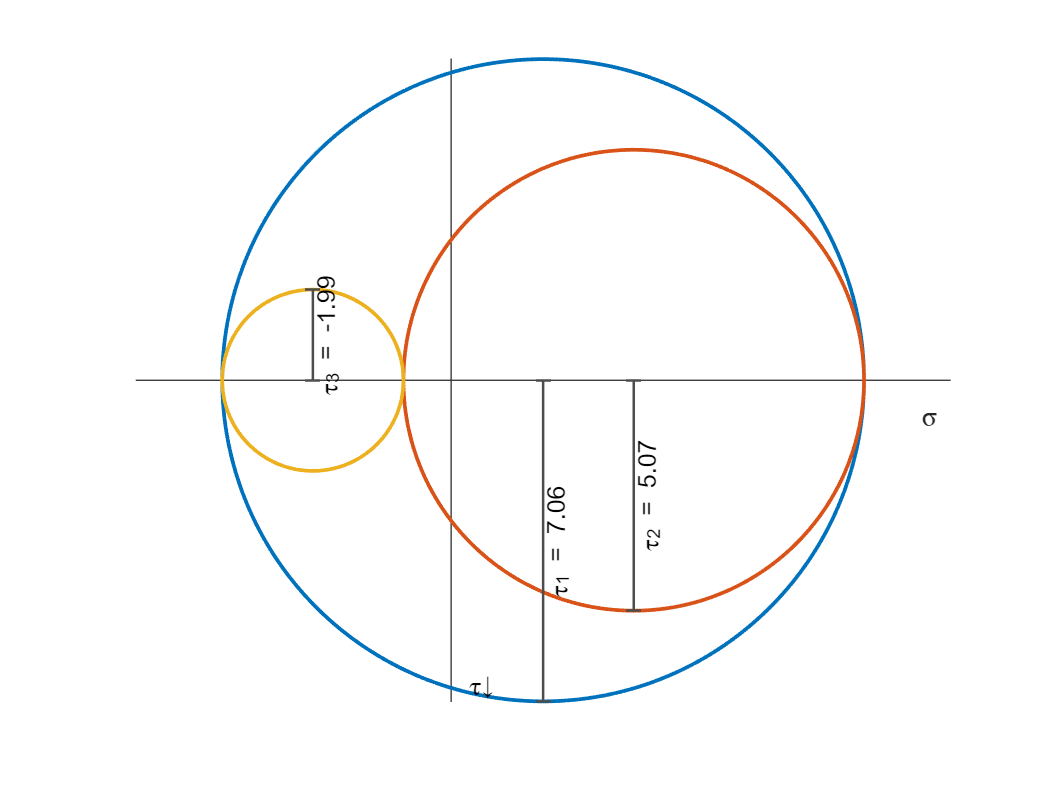

settings.showTicks = false;
settings.showPrincipal = false;
settings.showMaxShear = true;
mohrsCircle3D(S,settings);

function mohrsCircle3D(sigma,settings)

    measLW = 1;
    circLW = 1.5;
    grey = [0.3 0.3 0.3];
    lGrey = [0.7 0.7 0.7];
    prec = 3; % precision for display
    
    % Principle stresses
    lambda = eigs(sigma);
    sigmap = sort(lambda,"Descend","ComparisonMethod","abs");

    % Centers
    c1 = 0.5*(sigmap(1)+sigmap(2));
    c2 = 0.5*(sigmap(1)+sigmap(3));
    c3 = 0.5*(sigmap(2)+sigmap(3));
    
    % Circle radii
    r1 = 0.5*(sigmap(1) - sigmap(2));
    r2 = 0.5*(sigmap(1) - sigmap(3));
    r3 = 0.5*(sigmap(2) - sigmap(3));
    
    % Plot circles
    theta = linspace(0,2*pi,500);
    xc = cos(theta);
    yc = sin(theta);
    
    plot(r1*xc+c1,r1*yc,"LineWidth",circLW)
    hold on
    plot(r2*xc+c2,r2*yc,"LineWidth",circLW)
    plot(r3*xc+c3,r3*yc,"LineWidth",circLW)
    axis equal 

    % Sigma labels
    if(settings.showPrincipal)
        rMaxNeg = max(abs([r1,r2,r3]));
        sigh = rMaxNeg*[1.2 1.0 0.8];
        for k = 1:3
            plot([0,sigmap(k)],[1 1]*sigh(k),"-|","LineWidth",measLW,"color",grey)
            plot([1 1]*sigmap(k),[0,sigh(k)],"color",lGrey)
            text(sigmap(k)/2,sigh(k)+rMaxNeg*0.025,"\sigma_" + num2str(k) + " = " + num2str(sigmap(k),prec),...
                "VerticalAlignment","top","HorizontalAlignment","center")
        end
    end

    % Tau labels
    if(settings.showMaxShear)
        [rSort,idx] = sort([r1,r2,r3],"descend","ComparisonMethod","abs");
        c = [c1 c2 c3];
        cSort = c(idx);
        
        for k = 1:3
            plot([1 1]*cSort(k),[0 rSort(k)],"k-_","LineWidth",measLW,"color",grey)
            text(cSort(k),rSort(k)/2,"\tau_" + num2str(k) + " = " + num2str(rSort(k),prec),...
                "VerticalAlignment","top","HorizontalAlignment","center","Rotation",90)
        end
    end        

    % Axis settings
    ax = gca;
    ax.XAxisLocation = "Origin";
    ax.YAxisLocation = "Origin";
    ax.Clipping = "off";
    ax.YDir = "reverse";
    axis equal
    box off
    if(settings.showTicks == false)
        xticks([])
        yticks([])
    else
        grid on
    end

    % Axis labels
    xlabel("\sigma")
    yLims = ylim;
    xLims = xlim;
    if(xLims(1)>0)
        ax.XLim(1) = 0;
    end
    text(0.02*diff(xLims),yLims(2),"\tau↓","VerticalAlignment","baseline")
    
end